## Modélisation de l'activité électrique du cerveau 

#### I. Système à 2 neurones

#### Q1 Exploration

On se propose ici de mettre en place un code avec curseurs pour représenter la variation des courbes s1, s2 selon la variatiation de différents paramètres

clear all;
close all;
clc;

% Définition des fonctions
Phi1 = @(x) max(0,x);
Phi2 = @(x, b) 1 ./ (1 + exp(-b*x));

function [t, s] = euler(W, B, s0, lambda, tspan, phi_choice, b_param)
    N = 1000;
    pas = tspan(2)/N;
    
    % Choisir la fonction selon phi_choice
    if phi_choice == 1
        Phi = @(x) max(0,x);
    else
        Phi = @(x) 1 ./ (1 + exp(-b_param*x));
    end
    
    f = @(t, s) -lambda * s + Phi(W * s + B); % equation
    
    t = zeros(N + 1, 1);
    s = zeros(N + 1, 2);
    
    t(1) = tspan(1);
    s(1, :) = s0;
    
    % Euler
    for i = 1:N
        f_i = f(t(i), s(i, :)');
        s(i+1, :) = s(i, :) + pas * f_i';
        t(i+1) = t(i) + pas;
    end
end

% Initialisation des paramètres
W = [1, 1; 1, 1];
B = [1; 1];
s0 = [1; 1];
lambda_val = 2;
tspan = [0 10];
phi_choice = 1; % 1 pour Phi1, 2 pour Phi2
b_param = 1; % Paramètre b pour Phi2

% Fonction de tracé
function tracer_graph(lambda_val, s_01, s_02, B1, B2, w11, w12, w21, w22, phi_choice, b_param)
    W = [w11, w12; w21, w22];
    B = [B1; B2];
    s0 = [s_01; s_02];
    tspan = [0 10];
    
    [t, s] = euler(W, B, s0, lambda_val, tspan, phi_choice, b_param);
    
    plot(t, s, 'LineWidth', 2);
    xlabel('Temps (t)', 'FontSize', 12);
    ylabel('États s_i(t)', 'FontSize', 12);
    grid on;
    legend('s_1(t)', 's_2(t)', 'Location', 'best', 'FontSize', 11);
    
    % Titre avec indication de la fonction choisie
    if phi_choice == 1
        titre = 'Modélisation avec Phi1: max(0,x)';
    else
        titre = sprintf('Modélisation avec Phi2: sigmoïde (b=%.1f)', b_param);
    end
    title(titre);
end

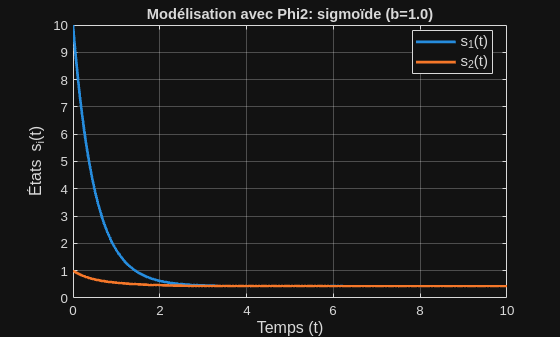

lambda_val =2;
s_01 =10;
s_02 =1;
B1 =1;
B2 =1;
w11 =1;
w12 =1;
w21 =1;
w22 =1;
b_param =1;
phi_choice = 2;
%% Tracé
tracer_graph(lambda_val, s_01, s_02, B1, B2, w11, w12, w21, w22, phi_choice, b_param);

#### Conclusion

Conclusion pertinente

####     II. Système à n neurones

#### Q2/ Exploration

%% Question 2 - Système à n neurones

clear all;
close all;
clc;

%% Définition du nombre de neurones
n = 5;

%% Fonctions

% Fonction d'activation selon phi_choice
function Phi = get_activation_function(phi_choice, beta)
    if phi_choice == 1
        % ReLU: max(0,x)
        Phi = @(x) max(0, x);
    else
        % Sigmoïde
        Phi = @(x) 1 ./ (1 + exp(-beta * x));
    end
end

% Méthode d'Euler
function [t, s] = euler2(W, B, s0, lambda, tspan, phi_choice, beta)
    n = length(s0);
    N = 1000;
    pas = (tspan(2) - tspan(1)) / N;

    Phi = get_activation_function(phi_choice, beta);
    
    f = @(t, s) -lambda * s + Phi(W * s + B); 
    
    t = zeros(N + 1, 1);
    s = zeros(N + 1, n);
    s(1, :) = s0';
    
    for i = 1:N
        f_i = f(t(i), s(i, :)'); 
        s(i+1, :) = s(i, :) + pas * f_i'; 
        t(i+1) = t(i) + pas;
    end
end

% Fonction de génération de matrice W
function W = generate_W_matrix(n, w_mode, w_diag, w_off, w_scale)
    switch w_mode
        case 1  % Uniforme
            W = w_off * ones(n, n);
            
        case 2  % Diagonale
            W = w_off * ones(n, n);
            W = W + (w_diag - w_off) * eye(n);
            
        case 3  % Aléatoire
            W = w_scale * (2 * rand(n, n) - 1);
            
        case 4  % Identité
            W = w_diag * eye(n);
            
        case 5  % Symétrique
            W_temp = w_scale * (2 * rand(n, n) - 1);
            W = (W_temp + W_temp') / 2;
            
        otherwise
            W = ones(n, n);
    end
end

% Fonction de tracé
function tracer_graph2(n, lambda, beta, phi_choice, s0_vec, B_vec, W_mat)
    tspan = [0 10];
    
    % Convertir les vecteurs
    s0 = s0_vec(:);
    B = B_vec(:);
    
    % Résolution
    [t, s] = euler2(W_mat, B, s0, lambda, tspan, phi_choice, beta);
    
    % Tracé
    plot(t, s, 'LineWidth', 2);
    xlabel('Temps (t)', 'FontSize', 12);
    ylabel('États s_i(t)', 'FontSize', 12);
    grid on;
    
    % Légende
    legend_labels = arrayfun(@(i) sprintf('s_%d(t)', i), 1:n, 'UniformOutput', false);
    legend(legend_labels, 'Location', 'best', 'FontSize', 10);
    
    % Titre
    if phi_choice == 1
        func_name = 'ReLU: max(0,x)';
    else
        func_name = sprintf('Sigmoïde (β=%.1f)', beta);
    end
    title(sprintf('Système à %d neurones - %s - λ=%.2f', n, func_name, lambda), 'FontSize', 11);
end

%% Initialisation des paramètres par défaut
% Ces valeurs sont utilisées au premier lancement

% Paramètres de l'équation
lambda = 2;
beta = 1;
phi_choice = 1;  % 1 = ReLU, 2 = Sigmoïde

% Conditions initiales et externes (uniformes)
s0_uniform = 1;
B_uniform = 1;

% Paramètres de génération de la matrice W
w_mode = 2;      % 1=Uniforme, 2=Diagonale, 3=Aléatoire, 4=Identité, 5=Symétrique
w_diag = 2;
w_off = 0.5;
w_scale = 1;

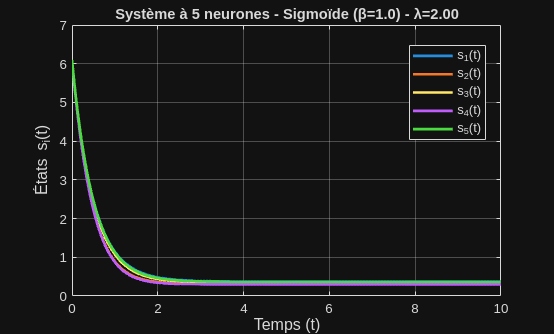

lambda =9.4;
s0_uniform =6.1;
B_uniform =1;
b_param =1;
w_mode = 3;
phi_choice = 2;

s0_vec = s0_uniform * ones(1, n);
B_vec = B_uniform * ones(1, n);

% Génération de la matrice W selon le mode choisi
W_mat = generate_W_matrix(n, w_mode, w_diag, w_off, w_scale);

% Tracé
tracer_graph2(n, lambda, beta, phi_choice, s0_vec, B_vec, W_mat);

disp('Matrice W:');

Matrice W:


disp(W_mat);

    0.9595    0.1898   -0.7652   -0.8290    0.4607
   -0.1223   -0.4756   -0.4066   -0.4750   -0.0228
   -0.7778    0.2057   -0.3624    0.6020    0.1571
   -0.4839    0.4224   -0.1517   -0.9416   -0.5254
   -0.1826   -0.5565    0.0157    0.8577   -0.0823



#### Q3/ Système à n neurones - On veut trouver numériquement W ∗ qui minimise H(W ) sur Mn (R)

- Calcul des dérivées partielles

%code

        2. Utilisation d'une descente de gradient sur la fonction H

%code

####     III. Prise en compte des incertitudes

#### Q4/ Propagation des incertitudes

- Hypothèse: les données initiales du système sont distribuées selon des lois normales indépendantes

%code

        2. Incertitude sur le calcul

%code

        3. Variabilité ur les données d'entrée

%code

#### **Q5/ **

%code